# very massive satellite in TNG50

Found this in the Cosmic Jellyfish sample: There is a very massive satellite galaxy(ies) in TNG50 with a mass above 1e12

Looking at the TNG50 satellite mass function we see 11 galaxies at different redshifts with a mass above 1e12

## load data

global DEFAULT_MATFILE_DIR
colors=brewermap(9,'Set1');

% load object table
load([ DEFAULT_MATFILE_DIR '\cosmic_jellyfish_objectTable.mat'])
% load galaxy properties
load([DEFAULT_MATFILE_DIR '\jf_galProperties_CJF.mat']);

zreds=round(100.*illustris.utils.snap2redshift(galProps.snap))./100;

## stellar mass vs host mass

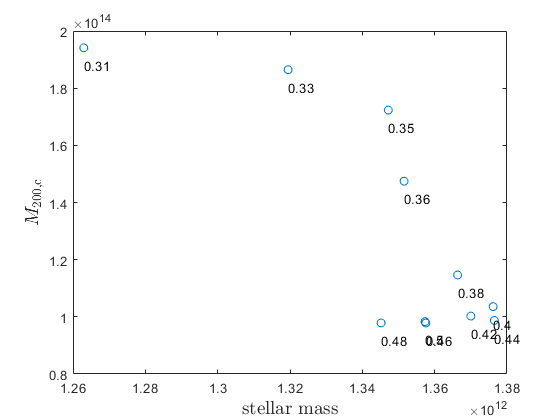

figure
plot(galProps.galStellarMass(ii),galProps.hostM200c(ii),'o')
yl=ylim;
hold on
for j=1:length(ii)
    text(galProps.galStellarMass(ii(j)),galProps.hostM200c(ii(j))-0.05*diff(yl),...
        num2str(zreds(ii(j))))
end

xlabelmine('stellar mass');
ylabelmine('$M_\mathrm{200,c}$');

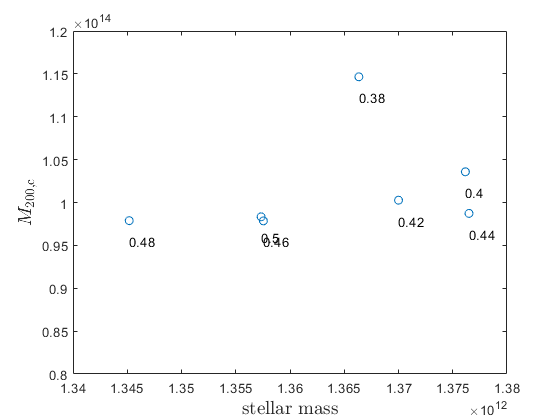



figure
plot(galProps.galStellarMass(ii),galProps.hostM200c(ii),'o')
yl=ylim;
hold on
for j=1:length(ii)
    text(galProps.galStellarMass(ii(j)),galProps.hostM200c(ii(j))-0.02*diff(yl),...
        num2str(zreds(ii(j))))
end
xlim([1.34 1.38].*1e12);
ylim([0.8e14 1.2e14]);
xlabelmine('stellar mass');
ylabelmine('$M_\mathrm{200,c}$');

The 11 galaxies are all in different snapshots with very similar mass - This suggests that they are actually the same galaxy seen in different snapshots. 

The next most massive galaxy is 

% mmask=galProps.galStellarMass<=1e12;
% 
% [mx,ix]=max(galProps.galStellarMass(mmask));
% fprintf('The next most massive galaxy has a mass of %s, it is from %s at redshift %s \n',...
%     num2str(log10(mx)),galProps.sim(ix),num2str(zreds(ix)));
% 

In TNG50 the next massive galaxy is  

% mask50=(objectTable.sim=="TNG50");
% sm=galProps.galStellarMass(mmask' & mask50);
% [mx2,ix2]=max(sm);
% fprintf('The next most massive galaxy in TNG50 has a mass of %s, it is from %s at redshift %s \n',...
%     num2str(log10(mx2)),galProps.sim(ix2),num2str(zreds(ix2)));

The mass ratio is pretty high, though not the overly so.

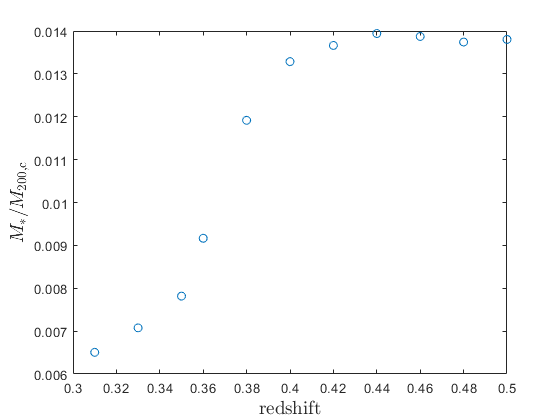

figure
plot(zreds(ii),galProps.galStellarMass(ii)./galProps.hostM200c(ii),'o')
% yl=ylim;
% hold on
% for j=1:length(ii)
%     text(galProps.stellarMass(ii(j)),galProps.stellarMass(ii(j))./galProps.hostM200c(ii(j))-0.05*diff(yl),...
%         num2str(zreds(ii(j))))
% end

xlabelmine('redshift');
ylabelmine('$M_\ast / M_\mathrm{200,c}$');

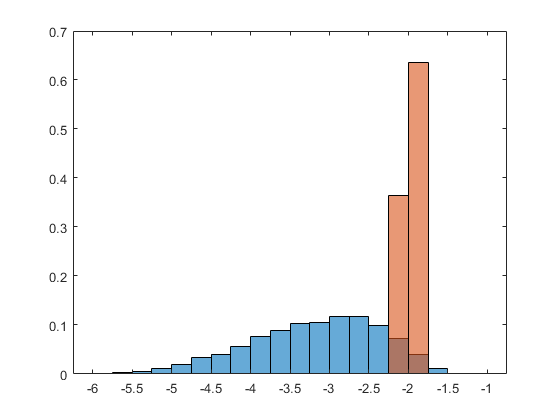


figure
be=-6:0.25:-1;
histogram(log10(galProps.galStellarMass./galProps.hostM200c),be,'normalization','probability')
hold on
histogram(log10(galProps.galStellarMass(ii)./galProps.hostM200c(ii)),be,'normalization','probability') 

% figure
% plot(galProps.stellarMass(ii),galProps.hostM200c(ii),'o')
% yl=ylim;
% hold on
% for j=1:length(ii)
%     text(galProps.stellarMass(ii(j)),galProps.hostM200c(ii(j))-0.02*diff(yl),...
%         num2str(zreds(ii(j))))
% end
% xlim([2.1e12 2.15e12]);
% ylim([0.8e14 1.2e14]);
% xlabelmine('stellar mass');
% % ylabelmine('$M_\mathrm{200,c}$');


My suspicion - This is not really a satellite but a misidentified central. Lets look at the distance from center of the host 

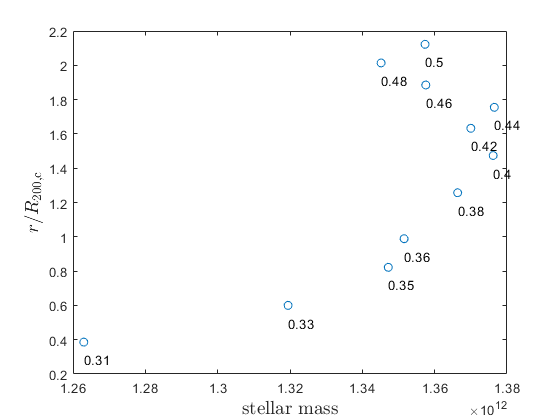

figure
plot(galProps.galStellarMass(ii),galProps.rpos(ii)./galProps.hostR200c(ii),'o')
yl=ylim;
hold on
 for j=1:length(ii)
     text(galProps.galStellarMass(ii(j)),galProps.rpos(ii(j))./galProps.hostR200c(ii(j))-0.05*diff(yl),...
         num2str(zreds(ii(j))))
 end

xlabelmine('stellar mass');
ylabelmine('$r/R_\mathrm{200,c}$');

Nope! This result acually points to a regular satellite - this may be the center of a group coming in: redshift and JF score are shown below and above, respectively. 

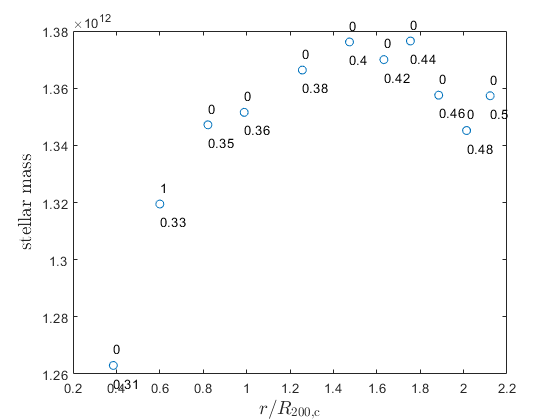

figure
plot(galProps.rpos(ii)./galProps.hostR200c(ii),galProps.galStellarMass(ii),'o')
yl=ylim;
hold on
 for j=1:length(ii)
     text(galProps.rpos(ii(j))./galProps.hostR200c(ii(j)),galProps.galStellarMass(ii(j))-0.05*diff(yl),...
         num2str(zreds(ii(j))))
     text(galProps.rpos(ii(j))./galProps.hostR200c(ii(j)),galProps.galStellarMass(ii(j))+0.05*diff(yl),...
         num2str(objectTable.score(ii(j))))
 end

ylabelmine('stellar mass');
xlabelmine('$r/R_\mathrm{200,c}$');

It's interesting that the stellar mass is dropping  - not by a lot but still losing about 15% of the stellar mass. Lets look at total stellar mass in the subfind: 

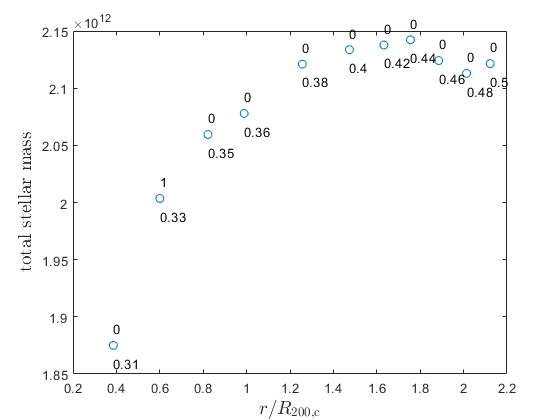

figure
plot(galProps.rpos(ii)./galProps.hostR200c(ii),galProps.stellarMass(ii),'o')
yl=ylim;
hold on
 for j=1:length(ii)
     text(galProps.rpos(ii(j))./galProps.hostR200c(ii(j)),galProps.stellarMass(ii(j))-0.05*diff(yl),...
         num2str(zreds(ii(j))))
     text(galProps.rpos(ii(j))./galProps.hostR200c(ii(j)),galProps.stellarMass(ii(j))+0.05*diff(yl),...
         num2str(objectTable.score(ii(j))))
 end

ylabelmine('total stellar mass');
xlabelmine('$r/R_\mathrm{200,c}$');